# lab1 - Pietro Alovisi

## Setup

% add path containing lab files
addpath('../LabFiles/Functions/');
addpath('../LabFiles/images/');

# Descrete Fourier transform

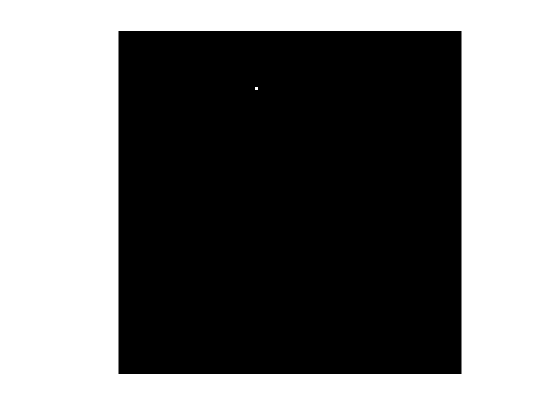

Fhat = zeros(128, 128);

p = 22; 
q = 52;
Fhat(p , q ) = 1;
figure(1);
showgrey(Fhat);

now let's compute the fourier transform

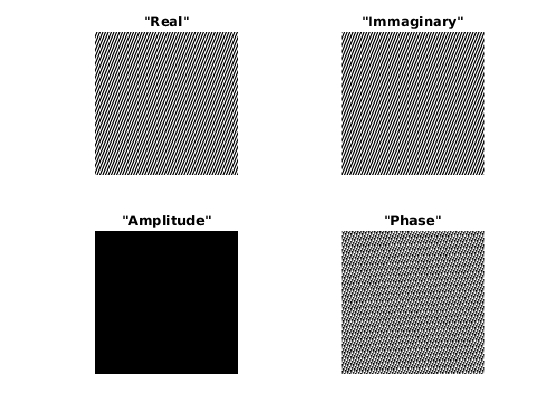


F = ifft2(Fhat);
Fabsmax = max(abs(F(:)));
figure(2);
subplot(2,2,1);
showgrey(real(F), 64, -Fabsmax, Fabsmax)
title "Real";

subplot(2,2,2);
showgrey(imag(F), 64, -Fabsmax, Fabsmax)
title "Immaginary";

subplot(2,2,3);
showgrey(log(abs(F)), 64, -Fabsmax, Fabsmax)
title "Amplitude";

subplot(2,2,4);
showgrey(angle(F), 64, -pi, pi)
title "Phase";

## Question 1

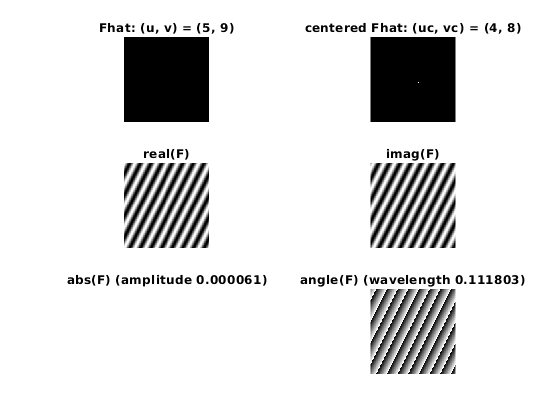

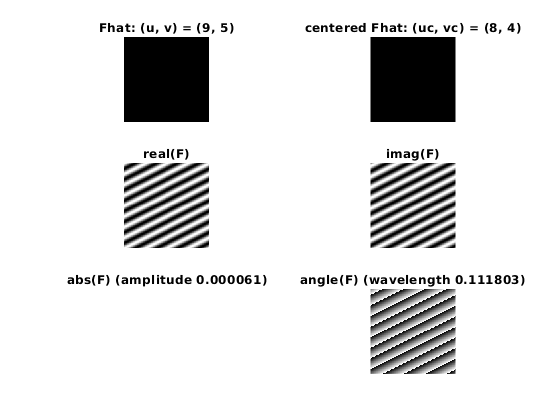

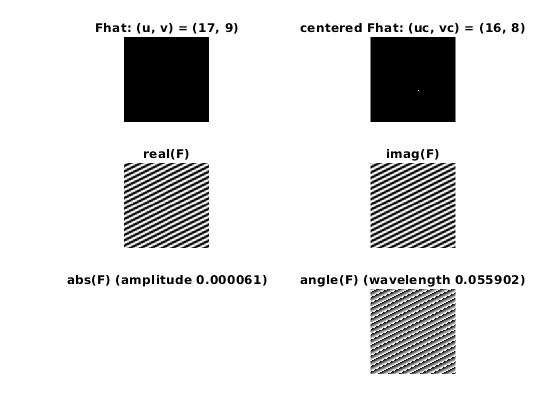

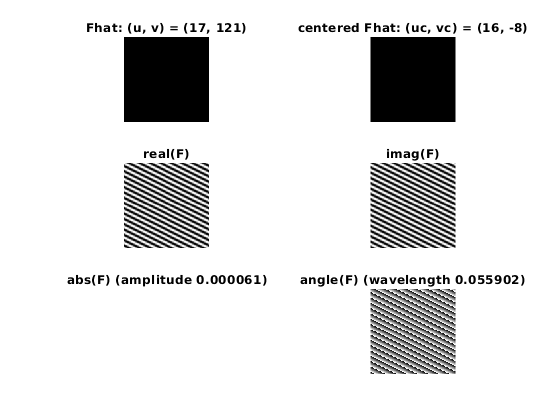

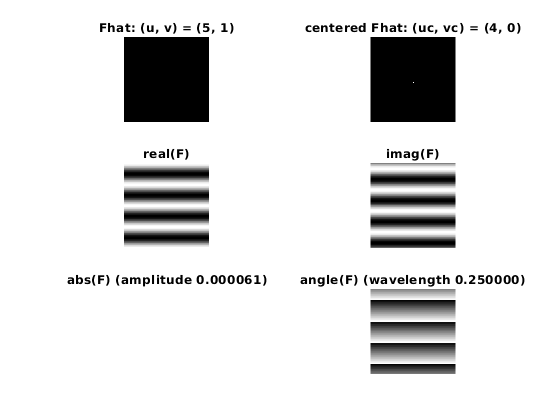

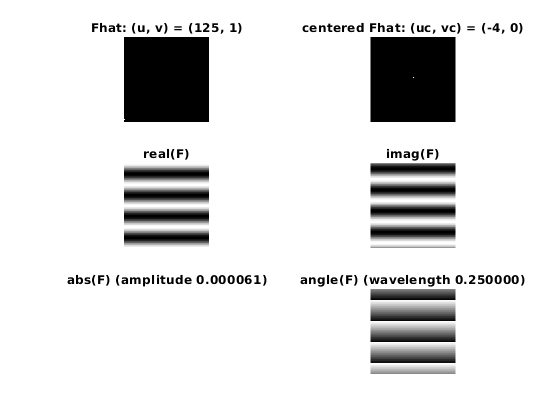

points = [5, 9; 9, 5; 17, 9; 17, 121;5, 1;125, 1];

for c =  1:size(points,1)
    f = figure(c+2);
    %title(f.Children(end),sprintf("Point %d, %d",points(c,1),points(c,2)));
    fftwave(points(c,1),points(c,2));
end

cazzeggio

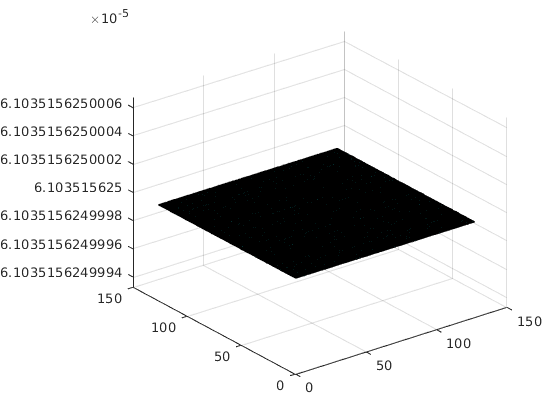

[X,Y]=meshgrid(1:128,1:128);
figure();
surf(X,Y,abs(F))

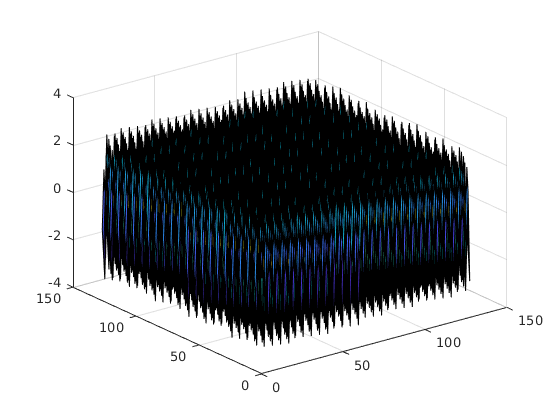

figure();
surf(X,Y,angle(F))

# Linearity

Create some blocky images, and compute their FFT:

F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

%computing fourier transform
Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

and then display their fourier spectral density:

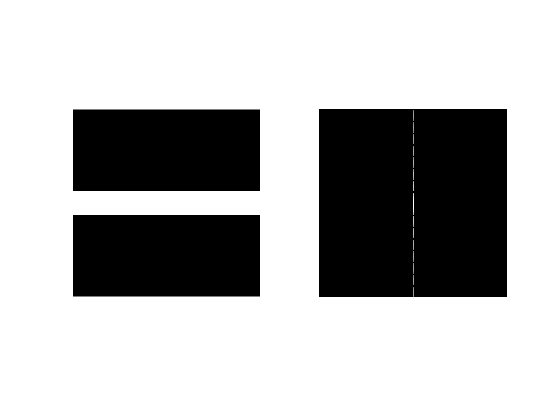

figure();
subplot(1,2,1);
showgrey(F);
subplot(1,2,2);
showgrey(log(1 + abs(fftshift(Fhat))));

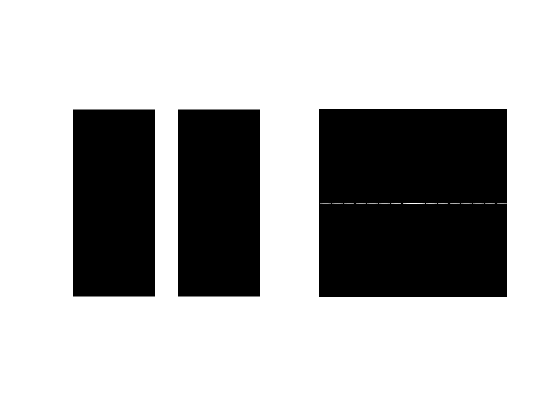

figure();
subplot(1,2,1);
showgrey(G);
subplot(1,2,2);
showgrey(log(1 + abs(fftshift(Ghat))));

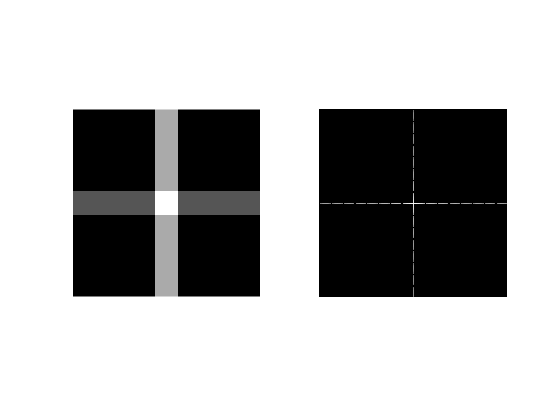

figure();
subplot(1,2,1);
showgrey(H);
subplot(1,2,2);
showgrey(log(1 + abs(fftshift(Hhat))));

## Multiplication

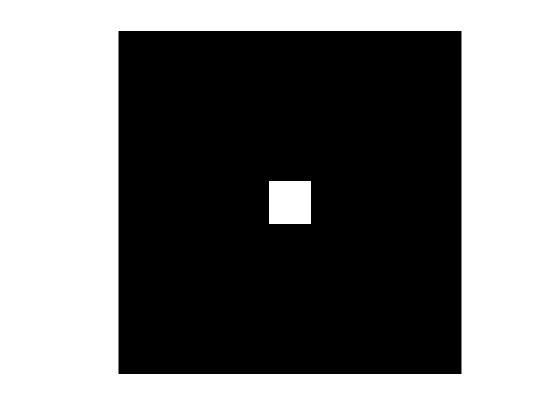

figure();
showgrey(F .* G);

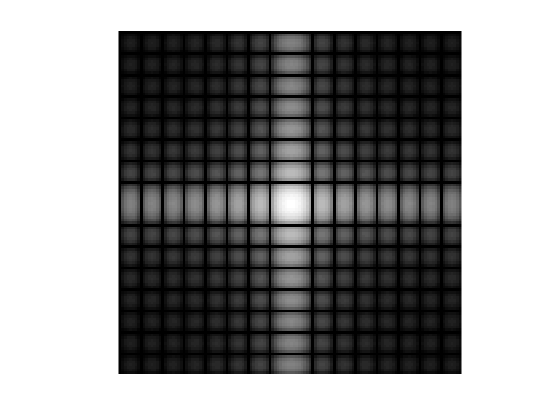

figure();
showfs(fft2(F .* G));

get the same result by convolution in the frequency domain.

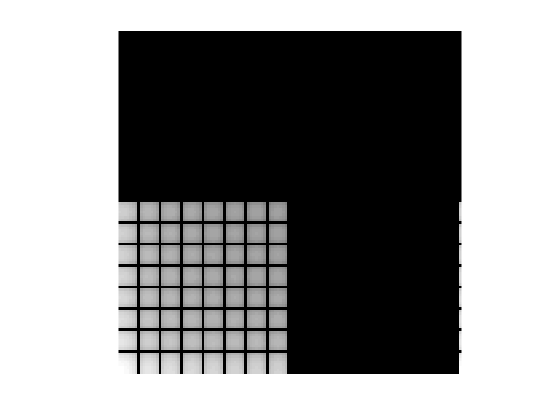

figure()
bigp=[Ghat,Ghat,Ghat;Ghat,Ghat,Ghat;Ghat,Ghat,Ghat];
showfs(imfilter(Ghat, Fhat));

%showfs(conv2(bigp,Fhat,'same'));

## Scaling

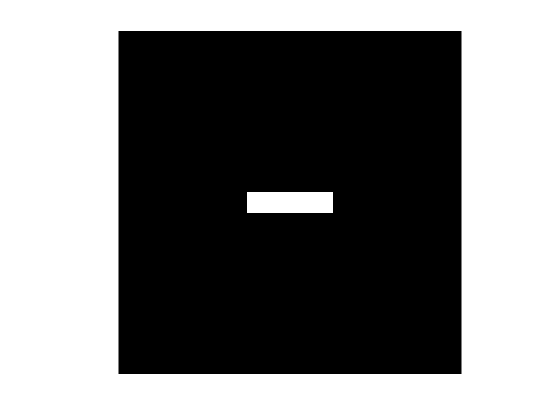

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];
showgrey(F);

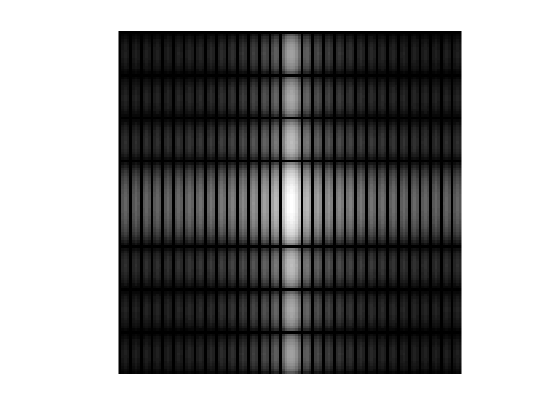

showfs(fft2(F));

## Rotation

alpha = 45;

alpha = 45

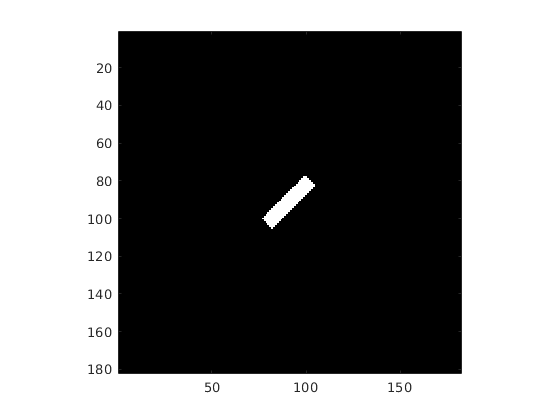


G = rot(F, alpha );
showgrey(G)

axis on

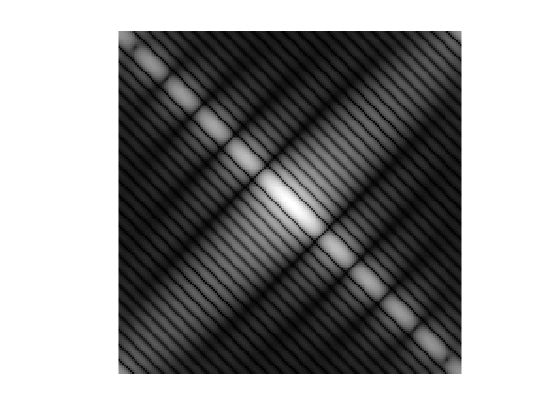

Ghat = fft2(G);
showfs(Ghat);

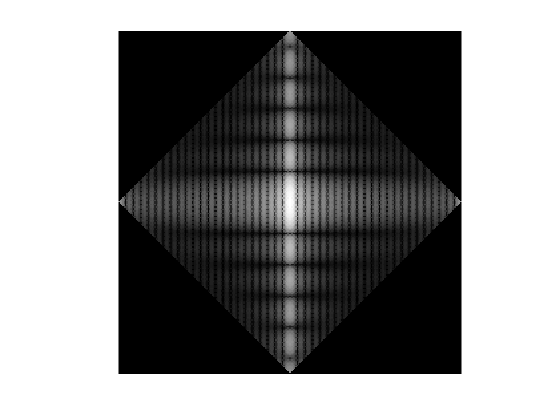


Hhat = rot(fftshift(Ghat), -alpha );
showgrey(log(1 + abs(Hhat)))

# Gaussian Filter

## Creating the function

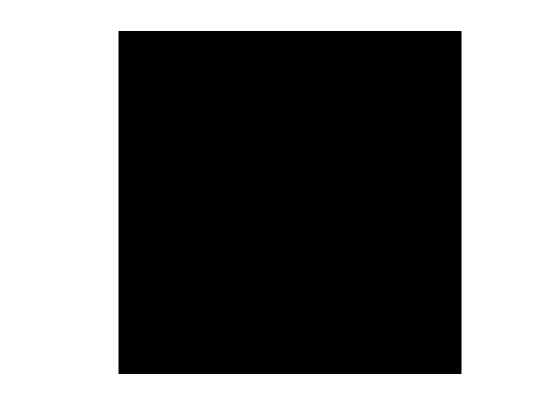

img = ones(64,64);

showgrey(img);

ans =     64    64


ans =     64    64


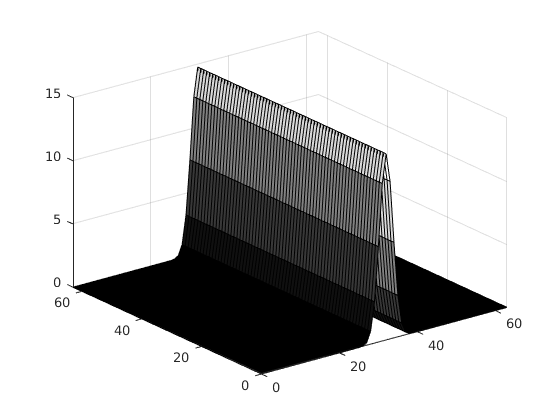

ans =     64    64


ans = 0

ans = 14.7411

p = gaussfft(img,3);

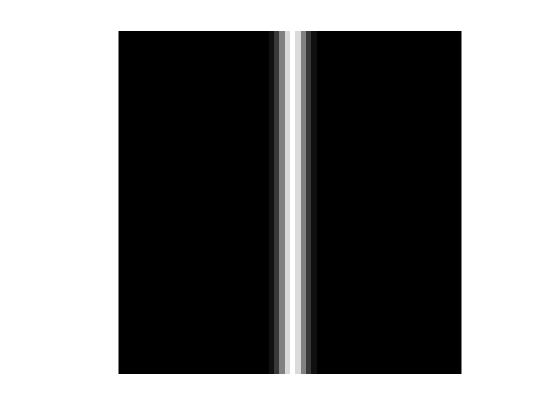

showgrey(p);

cose

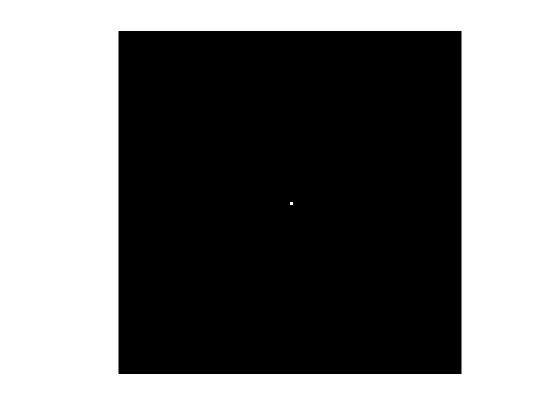

showgray(deltafcn(128, 128))

ans =    128   128


ans =    128   128


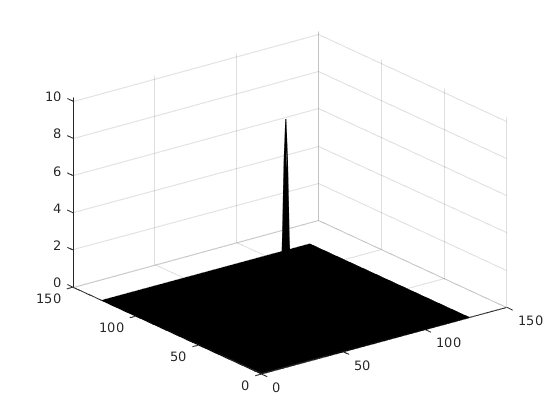

ans =    128   128


ans = 0

ans = 10.1859

psf = gaussfft(deltafcn(128, 128), 2);

p = psf

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

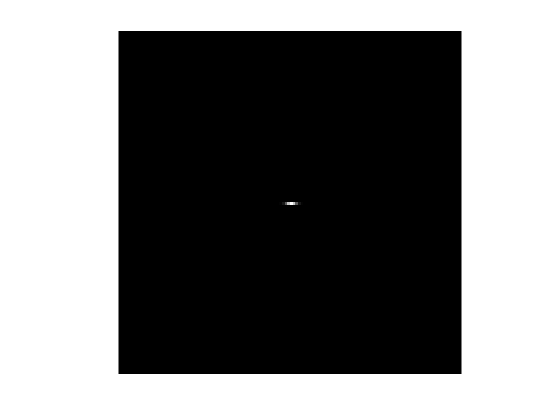

%psf = imgaussfilt(deltafcn(128, 128), 2);
%psf = discgaussfft(deltafcn(128, 128), 2);
figure();
showgrey(real(psf))

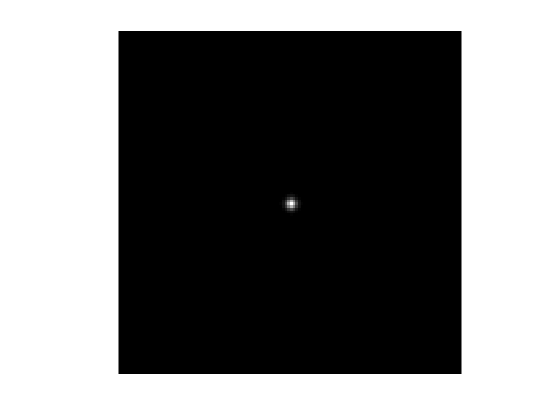

psf = discgaussfft(deltafcn(128, 128), 2);
showgrey(real(psf))

p-psf

ans =    -0.0681   -0.0557   -0.0478   -0.0424   -0.0085    0.0432    0.0794    0.0947    0.1099    0.1154    0.0901    0.0749    0.0740    0.0892    0.1206    0.1146    0.0520   -0.0244   -0.0828   -0.1048   -0.0989   -0.1154   -0.1327   -0.1062   -0.0762   -0.0724   -0.0545   -0.0244   -0.0172   -0.0330   -0.0504   -0.0721   -0.0779   -0.0506    0.0063    0.0538    0.0281   -0.0216   -0.0013    0.0357    0.0455    0.0522    0.0654    0.0620    0.0346   -0.0172   -0.0658   -0.0858   -0.0865   -0.0837
   -0.0295   -0.0269   -0.0255    0.0007    0.0369    0.0737    0.0910    0.0788    0.0409   -0.0015   -0.0149   -0.0139   -0.0409   -0.0531   -0.0279    0.0129    0.0503    0.0793    0.0686    0.0344    0.0041    0.0087    0.0524    0.0682    0.0558    0.0260    0.0015    0.0072    0.0459    0.0641    0.0342   -0.0142   -0.0249   -0.0029    0.0378    0.0322   -0.0023   -0.0083   -0.0010   -0.0169   -0.0609   -0.0980   -0.0898   -0.0566   -0.0514   -0.0556   -0.0361   -0.0113   -0.0168   

# Smoothing

Smooth an image.

# Function definition

function F = gaussfft(pic, t)
    d = 2^(floor(log2(min(size(pic)))));
    [X,Y] = meshgrid(0:d-1,0:d-1);
    filter = (1/(t*2*pi))*exp(-((X-(d/2)).^2+(Y-(d/2)).^2)/(2*t));
    size(filter)
    size(pic)
    
    Fpic = fft2(pic);
       
    Ffilter = fft2(filter);
    
    %surf(X,Y,Ffilter)
    F = ifft2(Fpic*Ffilter);
    surf(X,Y,real(F))
    size(F)
    sum(imag(F(:)))
    F = real(F);
    max(F(:))
end